close all;
clear figure;

% simulation parameters
num_runners = 5000;
num_sample_times = 100;
runner_mean_speeds = rand(num_runners,1)*4 + 3;
runner_mean_speeds(1:4) = 3.5:6.5; % hard code first 4 runners
runner_speeds = repmat(runner_mean_speeds,1,num_sample_times);
headwind = randn(num_runners, num_sample_times) * 0.1;
runner_speeds = runner_speeds - headwind;
distances = linspace(0,42.195,num_sample_times);

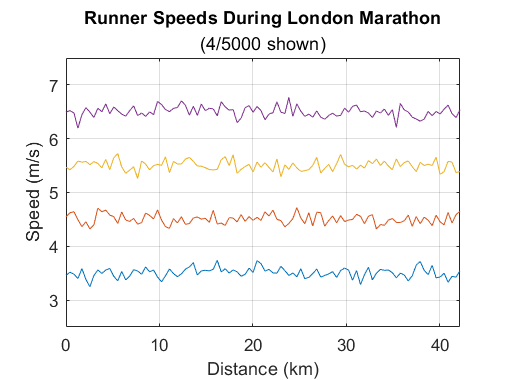

% plot 4 of the runner's speed throughout points along the race
plot(distances, runner_speeds(1,:)); hold on;
plot(distances, runner_speeds(2,:));
plot(distances, runner_speeds(3,:));
plot(distances, runner_speeds(4,:));
title('Runner Speeds During London Marathon');
subtitle('(4/5000 shown)')
xlabel('Distance (km)')
ylabel('Speed (m/s)')
grid on
axis([0 42.195 2.5 7.5]);
hold off;
saveas(gcf,'RunnerSpeeds.png')

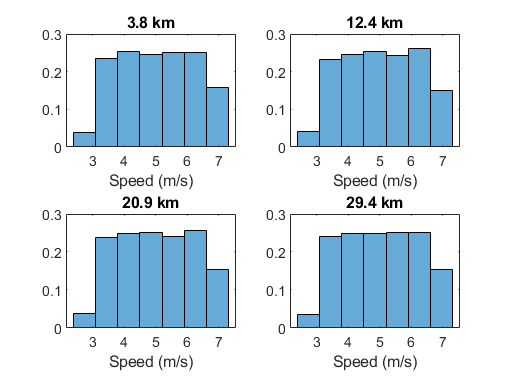

% create distribution for different points along the course
figure(2)
subplot(2,2,1)
histogram(runner_speeds(:,10),7,'Normalization','pdf')
title('3.8 km')
xlabel('Speed (m/s)')
subplot(2,2,2)
histogram(runner_speeds(:,30),7,'Normalization','pdf')
title('12.4 km')
xlabel('Speed (m/s)')
subplot(2,2,3)
histogram(runner_speeds(:,50),7,'Normalization','pdf')
title('20.9 km')
xlabel('Speed (m/s)')
subplot(2,2,4)
histogram(runner_speeds(:,70),7,'Normalization','pdf')
title('29.4 km')
xlabel('Speed (m/s)')
saveas(gcf,'CheckpointDist.png')

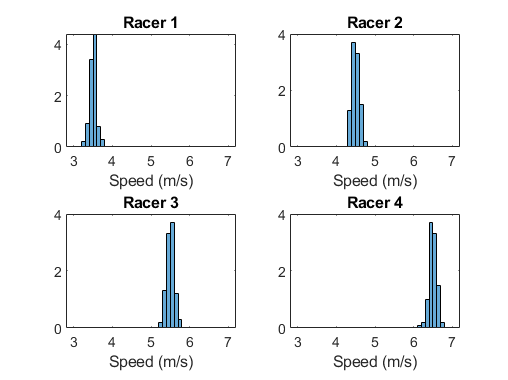

% create distribution for different racers
figure(3)
subplot(2,2,1)
histogram(runner_speeds(1,:),3:0.1:7,'Normalization','pdf')
title('Racer 1')
xlabel('Speed (m/s)')
subplot(2,2,2)
histogram(runner_speeds(2,:),3:0.1:7,'Normalization','pdf')
title('Racer 2')
xlabel('Speed (m/s)')
subplot(2,2,3)
histogram(runner_speeds(3,:),3:0.1:7,'Normalization','pdf')
title('Racer 3')
xlabel('Speed (m/s)')
subplot(2,2,4)
histogram(runner_speeds(4,:),3:0.1:7,'Normalization','pdf')
title('Racer 4')
xlabel('Speed (m/s)')
saveas(gcf,'RunnerDist.png')